# FIR interpolateur d'ordre zéro

clearvars;
close all;
M =10     % factor_surech

M = 10

hint=ones(1,M)

hint =      1     1     1     1     1     1     1     1     1     1


x=[1 2 3 4 5 6 7 8 7 6 5 4 3 2 1 ] % initial signal

x =      1     2     3     4     5     6     7     8     7     6     5     4     3     2     1


xup=[]  % x upsampled


xup =

     []



for i=1:length(x)
    xup=[xup x(i) zeros(1,M-1)]
end

xup =      1     0     0     0     0     0     0     0     0     0


xup =      1     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0


xup =      1     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0


xup =      1     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0


xup =      1     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     5     0     0     0     0     0     0     0     0     0


xup =      1     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     5     0     0     0     0     0     0     0     0     0


xup =      1     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     5     0     0     0     0     0     0     0     0     0


xup =      1     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     5     0     0     0     0     0     0     0     0     0


xup =      1     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     5     0     0     0     0     0     0     0     0     0


xup =      1     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     5     0     0     0     0     0     0     0     0     0


xup =      1     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     5     0     0     0     0     0     0     0     0     0


xup =      1     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     5     0     0     0     0     0     0     0     0     0


xup =      1     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     5     0     0     0     0     0     0     0     0     0


xup =      1     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     5     0     0     0     0     0     0     0     0     0


xup =      1     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     5     0     0     0     0     0     0     0     0     0


tiledlayout(4,1)
nexttile; stem(0:length(x)-1,x)
hold on;
nexttile; stem(0:length(xup)-1,xup)
xint=conv(xup,hint)  % x interpolated

xint =      1     1     1     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2     2     2     3     3     3     3     3     3     3     3     3     3     4     4     4     4     4     4     4     4     4     4     5     5     5     5     5     5     5     5     5     5


nexttile; stem(0:length(xint)-1,xint)


## Filtre moyenneur de lissage

N =6     % factor_surech

N = 6

hmean=ones(1,N)

hmean =      1     1     1     1     1     1


xfiltered=conv(xint,hmean)  % x interpolated

xfiltered =      1     2     3     4     5     6     6     6     6     6     7     8     9    10    11    12    12    12    12    12    13    14    15    16    17    18    18    18    18    18    19    20    21    22    23    24    24    24    24    24    25    26    27    28    29    30    30    30    30    30


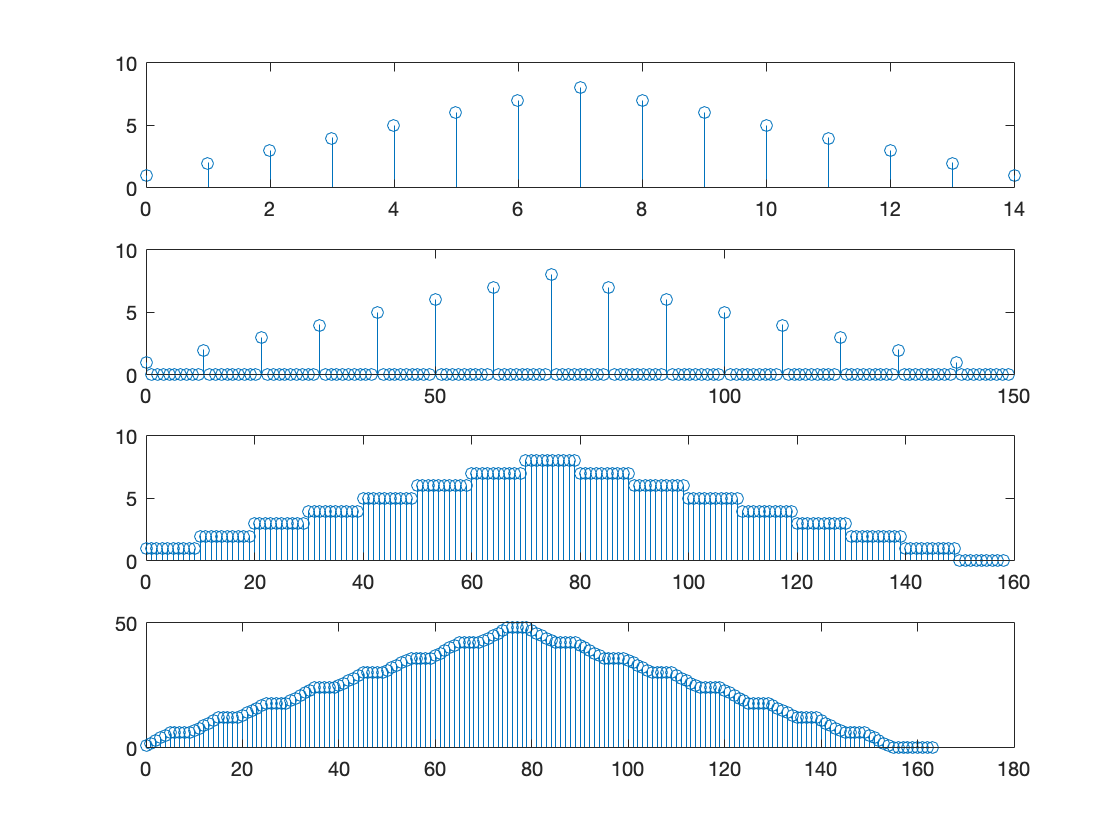

nexttile; stem(0:length(xfiltered)-1,xfiltered)